# Homework 1

**Name:** Jackson Lee

**Due Date: 1/30/23**

clear, clc

## Problem #1 - Charge on capacitor: measured vs. theoretical 

**a) Set up measured data (No output)**

t_m = [11,29,35,53,67,81];
Q_m = [1.3,2.4,2.4,3.7,3.9,3.7];

**b) Set up theoretical values (No output)**

t_t = 9:1:93;
Q_t = 5.1 .* (1-(exp((-t_t)./50)));

**c) Plot**

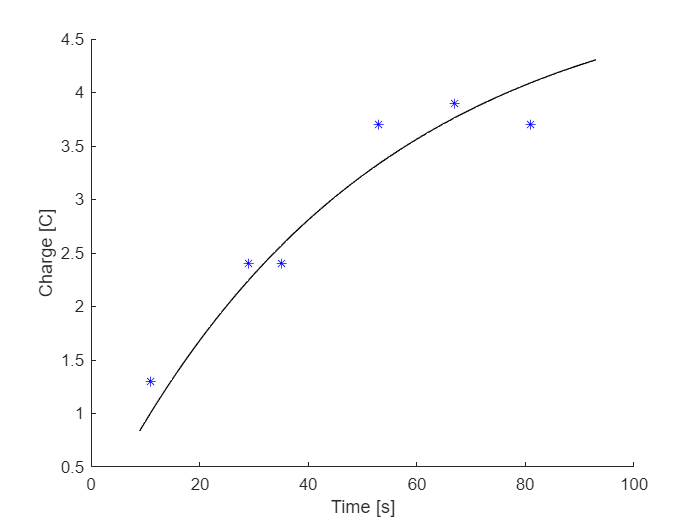

hold on
xlabel("Time [s]");
ylabel("Charge [C]");
plot(t_m,Q_m,"b*")
plot(t_t,Q_t,"k-")
hold off

## Problem #2 - Uniform beam with distributed load

% Set up variables
L=2000;
E=10000;
I=13000;
w0=170;
x=[0:16:L];


**a) Displacement, **$y\left(x\right)$

    Formula: $y=\frac{w_0 }{120\textrm{EIL}}\left(2L^2 x^3 -{\textrm{xL}}^4 -x^5 \right)$

% Displacement code
y=((w0)./(120.*E.*I.*L).*((2*(L^2).*(x.^3))-(x.*(L^4))-(x.^5)));

**b) Slope, **$\theta \left(x\right)=\frac{\textrm{dy}}{\textrm{dx}}$

    Formula: $\theta =$ $\frac{w_0 }{120\textrm{EIL}\;}\left(6L^2 x^2 -L^4 -5x^4 \right)$

% Slope code
dy=((w0)./(120.*E.*I.*L).*((6*(L^2).*(x.^2))-(L^4)-(5.*(x.^4))));

**c) Moment, **$M\left(x\right)=\textrm{EI}\;\frac{d^2 y}{{\textrm{dx}}^2 }$

    Formula: $M=$$\textrm{EI}\left(\frac{w_0 }{120\textrm{EIL}}\left(12L^2 x-20x^3 \right)\right)$  

% Moment code
M=((E*I)*((w0)./(120.*E.*I.*L)).*((12*(L^2)).*x)-(20.*(x.^3)));


**d) Shear, **$V\left(x\right)=\textrm{EI}\;\frac{d^3 y}{{\textrm{dx}}^2 }$

    Formula: $V=$ $\textrm{EI}\left(\frac{w_0 }{120\textrm{EIL}}\left(12L^2 -60x^2 \right)\right)$

% Shear code
V=((E*I)*((w0)./(120.*E.*I.*L)).*((12*(L^2))-(60.*(x.^2))));


**e) Plot a-d versus distance along the beam**

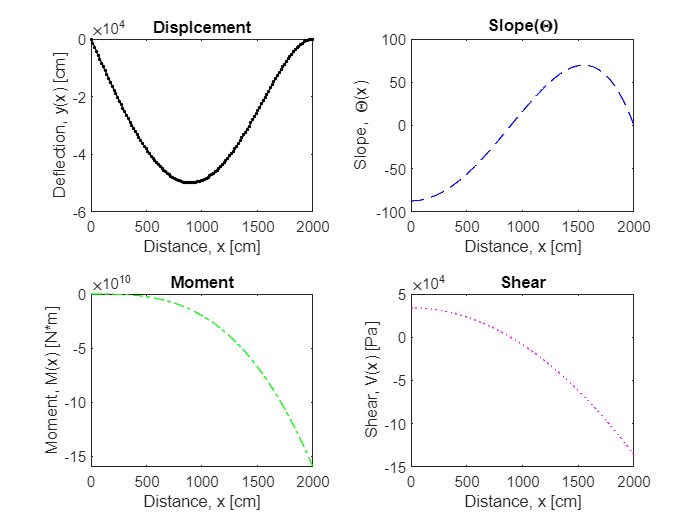

figure();
pain = tiledlayout(2,2);

nexttile
plot(x,y,"k.-")
title("Displcement")
xlabel("Distance, x [cm]")
ylabel("Deflection, y(x) [cm]")

nexttile
plot(x,dy,"b--")
title("Slope(\Theta)")
xlabel("Distance, x [cm]")
ylabel("Slope, \Theta(x)")

nexttile
plot(x,M,"g-.")
title("Moment")
xlabel("Distance, x [cm]")
ylabel("Moment, M(x) [N*m]")

nexttile
plot(x,V,"m:")
title("Shear")
xlabel("Distance, x [cm]")
ylabel("Shear, V(x) [Pa]")

## Problem #3 - Ellipsoid tank

**a) Test #1 - Provide title and units, no return value**

% Test #1 code

**b) Test #2 - Use defaults, return volume**

% Test #2 code

## Problem #4 - Manning's equation

**a) Display D matrix**

**b) Calculations for V using single line of code and display V vector**

**c) Calculations for V using single line of code in a loop**

## Problem #5 - Approximation and error

% Code for problem #5 here


## Problem #6 - Taylor series

**a) Calculate **$f_a \left(x\right)$** display in fprintf statement**

**b) Display exact answer and estimate the value of the function at the new value of x**

**c) Is this a reasonable approximation? Why or why not?**

     ANSWER HERE

**d) (Extra Credit) **

## ellipsoid_volume function from problem 3

function  V = ellipsoid_volume(a,b,plot_title,units)
%  Calculate the volume of horizontal ellipsoidal tank
%
%  Syntax:
%     ellipsoid_volume(a,b,plot_title,units) - creates plot
%     V = ellipsoid_volume(a,b) - calculates total tank volume
%     V = ellipsoid_volume(a,b,plot_title,units) - does both
%
%  Inputs:
%     a          - vertical semi-axis
%     b          - horizontal radius
%     plot_title - string holding plot title
%     units      – optional inits string, default = ‘m’.
%
%  Output:
%     V - total volume of the tank
end